TFH =
 
  9.656e32 s^4 + 1.702e34 s^3 - 1.898e34 s^2 - 3.344e35 s
  -------------------------------------------------------
  9.656e32 s^4 + 1.702e34 s^3 + 1.154e35 s^2 + 2.865e35 s
 
Continuous-time transfer function.
Model Properties


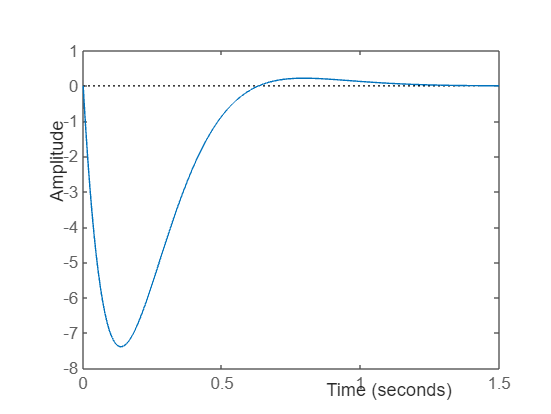

Kp = 1.5460e+03

Ki = 7.1429e+03

Kp = 1.5460e+03

Ki = 7.1429e+03

% Rocky_closed_loop_poles_23.m
%
% 1) Symbolically calculates closed loop transfer function of a disturbannce
% rejection PI control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp  to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this, the control constants can be found exactly 
%
% 5) Plot impulse and step response to see closed-loop behavior. 
%
% based on code by SG. last modified 2/25/23 CL

% clear all; 
% close all;



function [Kp, Ki] = plotPoleResponse(q)
    syms s a b l g Kp Ki    % define symbolic variables

    Hvtheta = -s/(l*s^2-g);
    
    K = Kp + Ki/s;                  % TF of the PI angle controller
    M = a*b/(s+a);                  % TF of motor (1st order model) 
    %  M = 1;                       % TF without motor
    
    
    % closed loop transfer function from disturbance d(t)totheta(t)
    % this is Theta(s)/D(s) (disturbance input, angle output)
    Hcloop = 1/(1-Hvtheta*M*K);   % use this for no motor feedback
    
    g = 9.81;

    tau_motor_L = 0.0573; 
    tau_motor_R = 0.0562; 
    alpha_motor_L = 1/tau_motor_L;
    alpha_motor_R = 1/tau_motor_R;
    beta_motor_L = 0.0026;
    beta_motor_R = 0.0025;

    a = (alpha_motor_R+alpha_motor_L)/2;
    b = (beta_motor_R+beta_motor_L)/2;
    
    omega_n = 4.4308;
    l = 0.4992;
    
    Hcloop_sub = subs(Hcloop); % sub parameter values into Hcloop
    
    p1 = -a/3;
    p2 = -a/3 + q*1i;
    p3 = -a/3 - q*1i;

    % target characteristic polynomial
    % if motor model (TF) is added, order of polynomial will increases
    tgt_char_poly = (s-p1)*(s-p2)*(s-p3);
    npoly = 3;
    
    % get the denominator from Hcloop_sub
    [~, d] = numden(Hcloop_sub);
    % find the coefficients of the denominator polynomial TF
    coeffs_denom = coeffs(d, s);
    % divide though the coefficient of the highest power term
    coeffs_denom = coeffs(d, s)/(coeffs_denom(end));
    % find coefficients of the target charecteristic polynomial
    coeffs_tgt = coeffs(tgt_char_poly, s);
    % solve the system of equations setting the coefficients of the
    % polynomial in the target to the actual polynomials
    solutions = solve(coeffs_denom(1:npoly-1) == coeffs_tgt(1:npoly-1),  Kp, Ki);
    
    % display the solutions as double precision numbers
    Kp = double(solutions.Kp);
    Ki = double(solutions.Ki);
    
    % reorder coefficients for the check polynomial 
    for ii = 1:length(coeffs_denom)
        chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
    end
    closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), npoly );
    
    
    % Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);
    % TFH = TFstring
    
    figure
    impulse(TFH);   %plot the impulse reponse
    % figure; hold on;
    % step(TFH);       %plot the step response
end

% plotPoleResponse(0)
% plotPoleResponse(1)
% plotPoleResponse(2)
% plotPoleResponse(3)
[Kp, Ki] = plotPoleResponse(4)

% plotPoleResponse(5)
% plotPoleResponse(10)

syms s a b l g    % define symbolic variables

Hvtheta = -s/(l*s^2-g);

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 

% closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K);   % use this for no motor feedback

g = 9.81;

tau_motor_L = 0.0573; 
tau_motor_R = 0.0562; 
alpha_motor_L = 1/tau_motor_L;
alpha_motor_R = 1/tau_motor_R;
beta_motor_L = 0.0026;
beta_motor_R = 0.0025;

a = (alpha_motor_R+alpha_motor_L)/2

a = 17.6228

b = (beta_motor_R+beta_motor_L)/2;

omega_n = 4.4308;
l = 0.4992;

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{126489623717466327\,s\,\left(\frac{7853689401653103}{1099511627776\,s}+\frac{1699858024482393}{1099511627776}\right)}{2814749767106560000\,\left(\frac{312\,s^{2}}{625}-\frac{981}{100}\right)\,\left(s+\frac{2480188700342477}{140737488355328}\right)}+1}$$


npoly = 3;
% get the denominator from Hcloop_sub
[~, d] = numden(Hcloop_sub);
% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s);

r = roots(coeffs_denom)

$$r = \left(\begin{array}{c} -0.17023400881057271611910322618268\\ -0.11630596860463749434830145025516+0.079196925136656168784113234215624\,\mathrm{i}\\ -0.11630596860463749434830145025516-0.079196925136656168784113234215624\,\mathrm{i} \end{array}\right)$$